# Demo PCA

    Análisis de Componentes Principales (PCA) para un sistema de detección de caídas.

#### Contexto

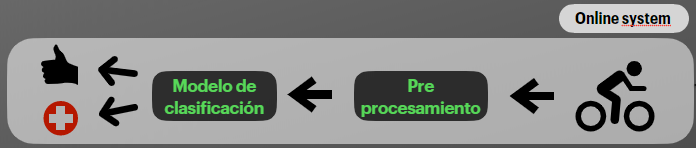

#### Extraer Datos y Características

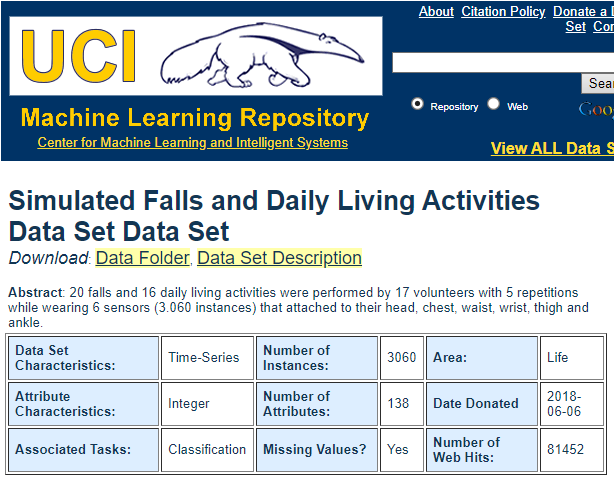

**Extracción de datos**

204 actividades 'caída'

204 actividades 'no caída'

Extracción de características

**Datos en el dominio del tiempo y en dominio de la frecuencia**

Caracterísiticas obtenidas de las señales:

- Promedio

- Máximos y mínimos

- Desviación estándar

- Mediana

- IQR

showPlots

**Guardar todos los datos en una sola matriz**

40 características:

- 204 Actividades de caída

- 204 Actividades de no caída

size(Features)

**Análisis PCA usando función de Matlab**

[coeff,Data,eigValues] = pca(Features,"NumComponents",6);
sort(eigValues,"descend")
Data

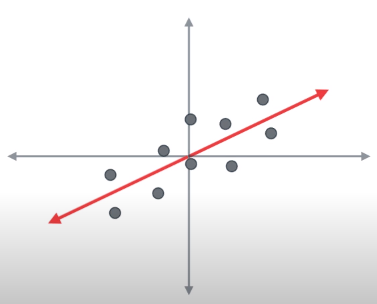        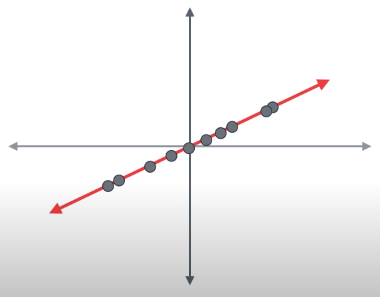

**Análisis PCA usando eigen vectores**

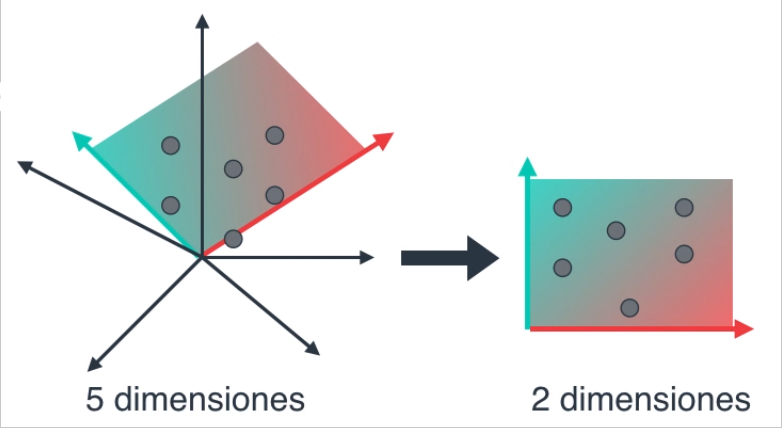        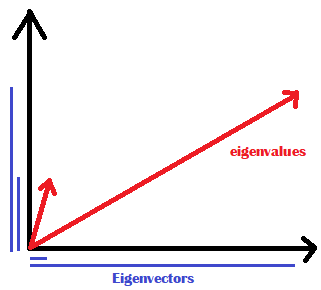

[vector,values] = eig( cov(Features) );
vector = vector*values;
eigenValues = diag(values);
hits = zeros(40,1);
maximo = max(max(vector));

for n = 1:40
   a = vector(:,n);
   rows = find(abs(a) > maximo/2);
   for p = 1:length(rows)
       numHits = rows(p);
       hits(numHits) = hits(numHits) + 1;
   end
end

hits'

ans =      1     1     2     0     0     1     1     1     0     0     0     1     1     1     1     1     0     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     1     0     0     0     0


i = find(hits>=1);
size(i)

ans =     14     1


**Cambio de dimensiones**

newData = zeros(408,length(i));
for n=1:length(i)
    newData(:,n) = Features(:,i(n));
end

size(newData)

ans =    408    14


**Scatter**

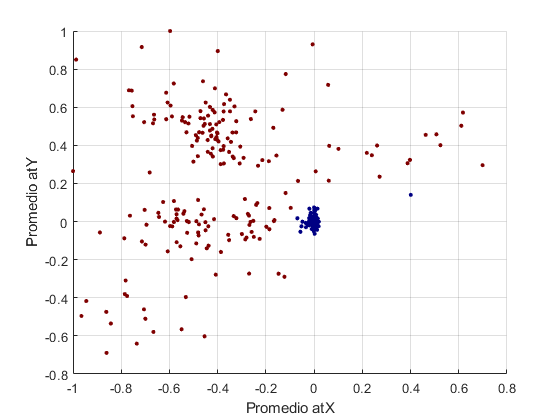


figure
scatter3(Features(:,1),Features(:,2),Features(:,3),10,Target,'filled');
xlabel('Promedio atX')
ylabel('Promedio atY')
zlabel('Promedio atZ')
colormap(jet);